# Algoritmos Numéricos por Computadora

# Tercer parcial - Primavera 2020

Cambia el nombre del script a Nombre (ej: Marcelo).

Sube tu archivo resultado a comunidad $\to$ Examen final antes de las 18:55 pm del martes 3 de junio.

- **Cuando yo abra o pruebe tu script deben desplegarse en la pantalla todos los resultados. **

- **Debes escribir al final del script todas las funciones que uses.**

- **El examen es individual, debes resolverlo sin ayuda de ninguna persona. **

- **Revisa con mucho cuidado tus respuestas. El examen será calificado de manera muy estricta.**

## 1. Uso eficiente de un lenguaje de programación matricial 

1.1   Calcula (en una línea) la norma euclidiana de un vector v. Verifica tu resultado usando la función norm, un vector cualquiera y la funcion isequal.

aux = rand(1,10);
sol11=sqrt(sum(aux.^2))
isequal(sol,norm(aux))

1.2 Calcula  $\sqrt{8\sum_{i=0}^{10000} \frac{1}{{\left(2n+1\right)}^2 }}$   (en dos o menos líneas)

sol12=sqrt(8*sum((2*(0:1:10000)+1).^-2))

1.3 Determina (en una línea) si una matriz es positiva definida: cuadrada, simétrica y con todos sus valores propios positivos. Verifica tu respuesta con las matrices: [2,2;2,5] y [2,4;4,5]

A=[2,2;2,5];
B=[2,4;4,5];

No es necesario checar si son cuadradas, pues una matriz no cuadrada NO es simetrica.

sol13a=all(eig(A)>0)&&issymmetric(A)
sol13b=all(eig(B)>0)&&issymmetric(B)

1.4 Se tiene un vector de n elementos. Escribe el código necesario para agregar un nuevo valor al vector, recorriendo los primeros valores (perdiendo el primero)  e insertando el nuevo valor en la última posición. Ejemplo, si v=[1,2,3,4], al agregar el 5 se tiene v=[2,3,4,5].

v=[1,2,3,4];
new=5; %nuevo valor
v=[v(2:end),new]

Puedes (debes) usar este código en la respuesta de la pregunta 3.

## 2. Errores numéricos de las soluciones computacionales

2.1 En la siguiente operación, ¿por que el resultado no es verdadero (1)? 

res = 7/100*100 - 7;
isequal(res,0)

ans = logical
   0


Por que aunque parece que es lo mismo, matlab no maneja tan bien las fracciones que no son de 2^algo, y usa el eps(x) que es el error maximo que pueden tener un nuumero sin que se vea afectado en matlab.

Aqui se calcula como (7/100) primero que es fraccion, esto genera un error de truncamiento pues MATLAB no puede representar de manera exacta un 0.07

Al tener un 0.07 que no es preciso y miltiplicarlo por 100, esto evidentemente no nos va a dar un 7, por lo que al restarle 7 vamos a tener algo distinto de 0. (hint: es eps(7)).

2.2 ¿A qué es igual res en la pregunta anterior? (Hint: la respuesta tiene que ver con la resolución de Matlab en el rango de valores de 7)

isequal(res, x) 

isequal(res,eps(7))

ans = logical
   1


2.3 El método de encripción RSA usa dos llaves, una pública (n,e) y una privada (n,d), y se basa en la siguiente igualdad matemática para encriptar y desencriptar un mensaje m

 ${\left(m^e \right)}^d =m={\left(m^d \right)}^e$  (donde las operaciones se hacen módulo n).

Por ejemplo, para encriptar letras minúsculas (ASCII)

n=33;
e=3;
d=7;
m = 'v';                        % letra a transmitir
ms = double(m) - double('a');   % mensaje ms<n            
c = mod(ms^d,n);                % mensaje encriptado
mr = mod(c^e,n);                % mensaje desencriptado
str = char(mr + double('a')) 

str = 'v'

isequal(ms,mr)                  % letra transmitida = letra recibida

ans = logical
   1


Sin embargo, si usamos las siguentes llaves podemos no desencriptar correctamente el mensaje :(

Caso favorable, m='b'

n=35;
e=5;
d=29;
m = 'b';                        
ms = double(m) - double('a') 

ms = 1

c = mod(ms^d,n);
eps(ms^d)

ans = 2.2204e-16

mr = mod(c^e,n);
isequal(ms,mr)

ans = logical
   1


Caso desfavorable, m='v'

n=35;
e=5;
d=29;
m = 'v';                        
ms = double(m) - double('a')

ms = 21

c = mod(ms^d,n);
eps(ms^d)

ans = 3.7779e+22

mr = mod(c^e,n);
isequal(ms,mr)

ans = logical
   0


Explica por qué pasa esto (Hint: ¿qué error numérico se presenta? ¿Por qué?)

Si recordamos las clases de Algebra superior, sabemos que se puede desglosar el mod de un prod en un prod de mods, esto es lo que hace MATLAB para trabajar con numeros tan grandes, pero al desarrollarlos, quedan cosas muy diferentes. 

Tenemos 21^29 que es un numero muy grande y MATLAB lo convierte en exponenciales. Aqui entra eps(ms^d) que es el numero mas grande que se le puede sumar a otro sin que se vea afectado, pero aunque para efectos de algun numero en matlab no afecta, al meterle ms^d a mod, tenemos que considerar el error de la maquina. En el caso favorable, el error de la maquina es chico y no afecta, pero en el caso desfavorable, el error es enorme por lo que no se puede desencriptar. 

caso favorable=> eps chico eps(1^29)

caso desfavorable => eps grande eps(21^29)

Sera necesario usar una platadorma que no tenga este error por el punto flotante para poder desencriptar y encriptar cosas.

## 3. Entendimiento del funcionamiento de métodos numéricos

Para mejorar la exactitud del método ABM, pueden usarse las siguientes fórmulas.

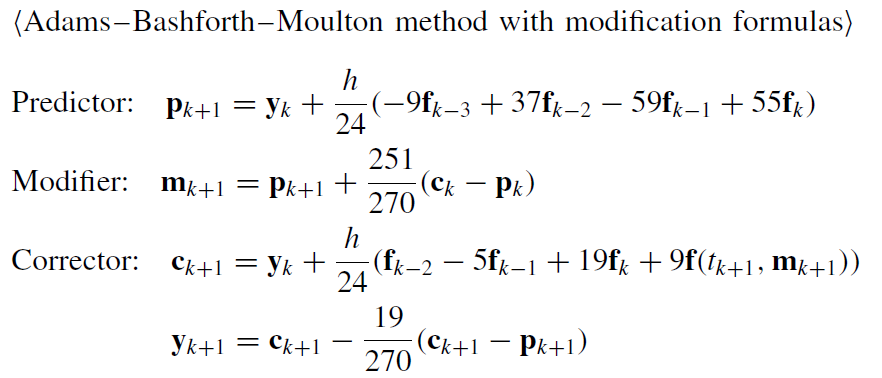

AL final de este script codifica el método mejorado (ABM4mo) utilizando estas fórmulas y minimizando el número de evaluaciones de la función f y minimizando la cantidad de memoria utilizada.

Escribe y prueba tu método por partes:

3.1 Codifica el método para *f* escalar

3.2 Codifica el método para *f* vectorial

3.3 Codifica el método guardando los valores calculados de* f* en un vector (matriz)

3.4 Codifica el método guardando solo los últimos 4 valores calculados de* f* (y los últimos 2 de *p* y de *c*).

Al final, solo deja en el script tu mejor solución.

Prueba tu función en cada parte resolviendo el siguiente problema de valor inicial (usa h=0.05):

$y^{\prime } =f\left(x,y\right)=\frac{1}{2}\left(1+x\right)y^2$         $y\;\left(0\right)=1$          t in [0,1]

Grafica la solución.

f = @(x,y) (1/2)*(1+x)*y^2;
y0 = 1;
t0 = 0;
tf = 1;
h = 0.05;
[t,y] = ABM4(f,y0,t0,tf,h);
plot(t,y)

## 4. Solución de ecuaciones diferenciales y sistemas lineales

Usando el método de diferencias finitas, resuelve el siguiente problema de valores en la frontera:


$$7\frac{d^2 }{\mathrm{d}x^2 }y-2\frac{d}{\mathrm{d}x}y-y+t=0$$
         
$$y\left(0\right)=5\;,\;\;y\;\left(20\right)=8$$


4.1 Escribe las fórmulas de diferencias finitas (centrales)  para la segunda y primera derivadas $O\left(h^2 \right)$


$$y''_i=\frac{y_{i-1}-2y_i+y_{i+1}}{h^2}$$


4.2 Plantea el sistema de ecuaciones lineales correspondiente (con 100 puntos).

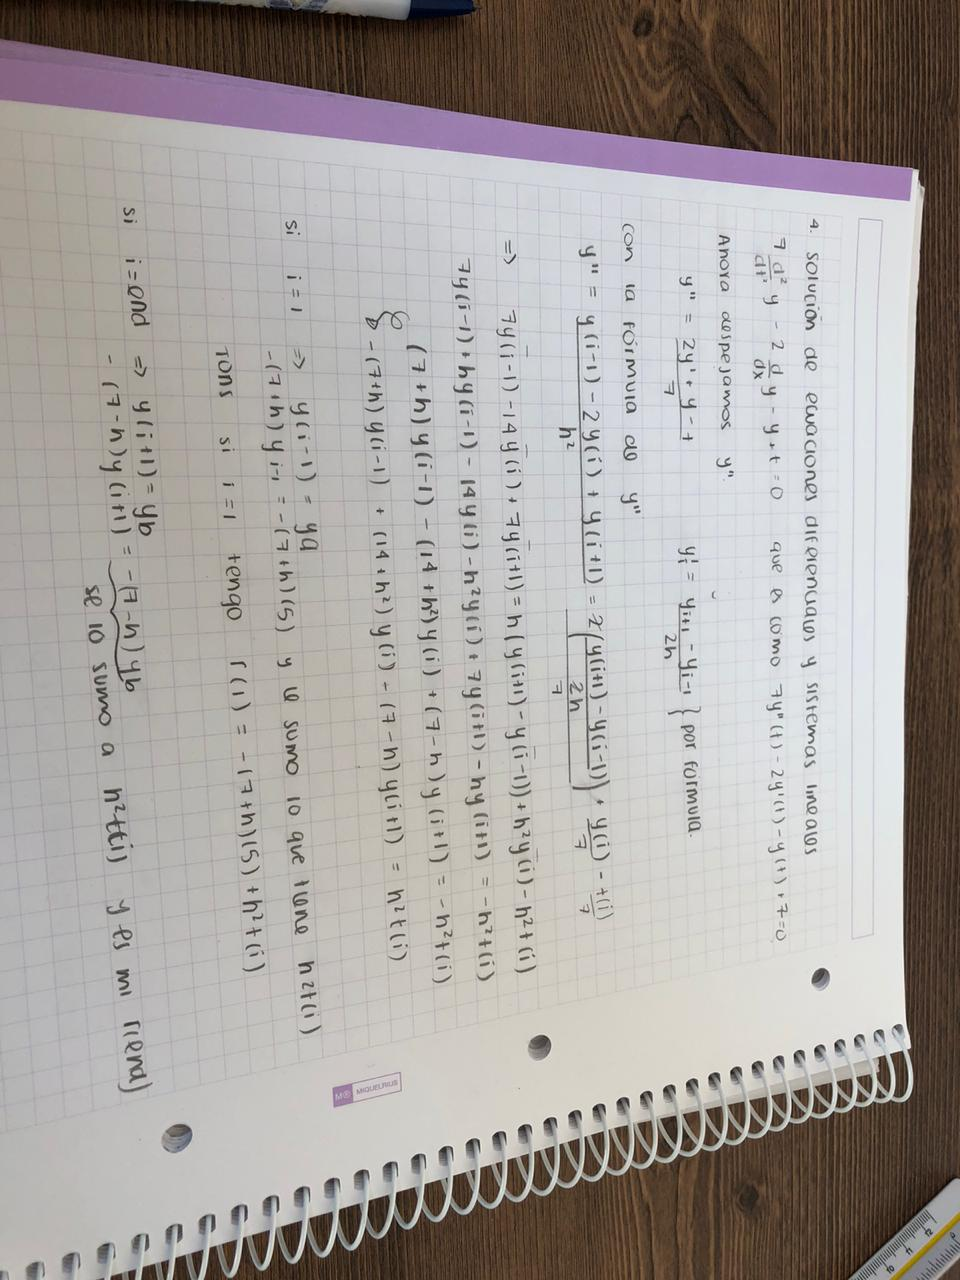

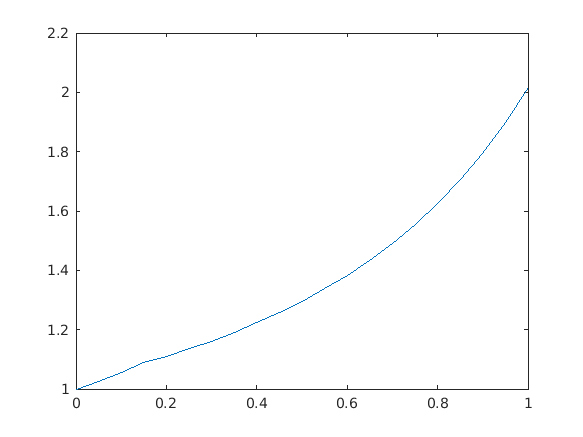

a=0;
b=20;
ya=5;
yb=8;

n=98; %Número de puntos interiores
h=(b-a)/(n+1); 

%tridiag
e=-(7+h)*ones(1,n); %y(i-1)
f=(14+h^2)*ones(1,n); %y(i)
g=-(7-h)*ones(1,n); %y(i+1)

t=a:h:b;

r=t*h^2;
r(1)=ya*(7+h)+a*h^2;
r(end)=yb*(7-h)+b*h^2;






4.3 Resuelve el sistema de ecuaciones lineales de manera eficiente

yTr=tridiag(e,f,g,r);

4.4 Grafica la solución *y(t)*.

plot(t,[ya;yTr;yb])

Funciones utilizadas

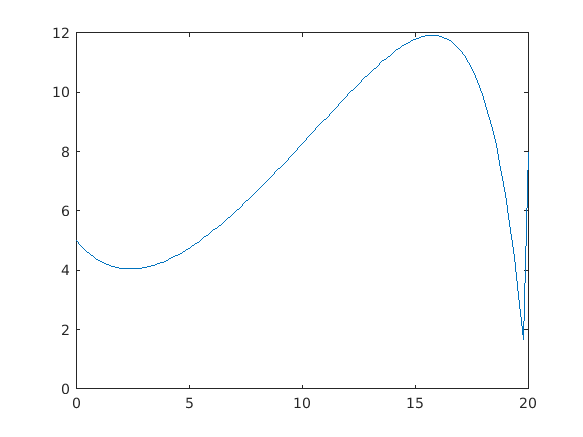

function [t,y] = ABM4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0),n);
    [~,yTemp]=odeRK4(f,y0,t0,t0+3*h,h);
    y(:,1:4)=yTemp;
    pkp=0;
    ckp=0;
    f3=f(t(1),y(:,1));%-3
    f2=f(t(2),y(:,2));%-2
    f1=f(t(3),y(:,3));%-1
    fi=f(t(4),y(:,4));%donde estoy
    %nota: no use el codigo de la 1 por que es mas eficiente solo evaluar
    %una vez como aqui.
    for i=4:n-1
        yi=y(:,i);
        pk=yi+(h/24)*(-9*f3+37*f2-59*f1+55*fi); %predictor

        mk=pkp+(251/270)*(ckp-pkp); %modifier
        ck=yi+(h/24)*(f2-5*f1+19*fi+9*f(t(i+1),mk)); %corrector
        y(:,i+1)=ck-(19/270)*(ck-pk); %y(:,i+1)
        f3=f2;%-3
        f2=f1;%-2
        f1=fi;%-1
        fi=f(t(i+1),y(:,1+i));%donde estoy
    end

end

function x = tridiag(e,f,g,r)
    n=length(f);
    for k = 2:n
        factor = e(k)/f(k-1);
        f(k) = f(k) - factor*g(k-1);
        r(k) = r(k) - factor*r(k-1);
    end
    x=zeros(n,1);
    x(n) = r(n)/f(n);
    for k = n-1:-1:1
        x(k) = (r(k)-g(k)*x(k+1))/f(k);
    end
end